load('./results/paper1/MyStat-Stat-RBF.mat');
ALL = [1:5 9:14];
STL = [1:5 14];
MTL = [9:14];

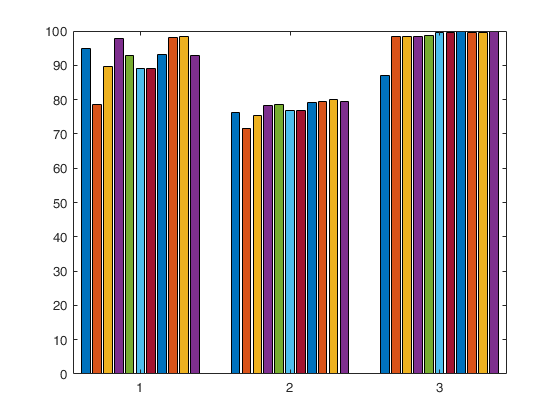

% benchmark
benchmark = [6 1 3];
T = Summary.Stats.Accuracy([6 1 3], ALL);
bar(T.Variables);

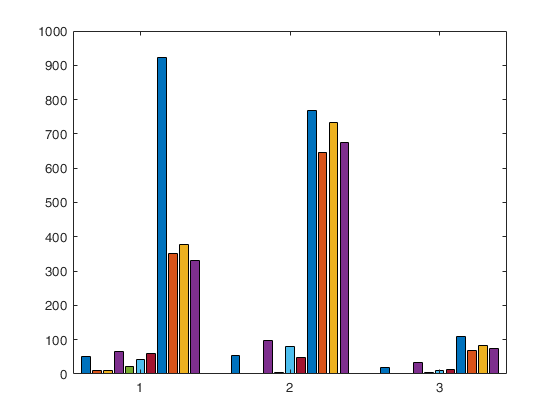

T = Summary.Stats.Time([6 1 3], ALL);
bar(T.Variables);

% monk
Monk = [7:14 6]

Monk =      7     8     9    10    11    12    13    14     6


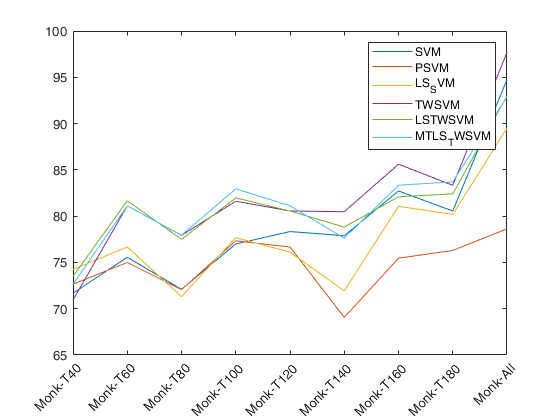

T = Summary.Stats.Accuracy(Monk, STL);
plot(T.Variables);
bar_table(T);

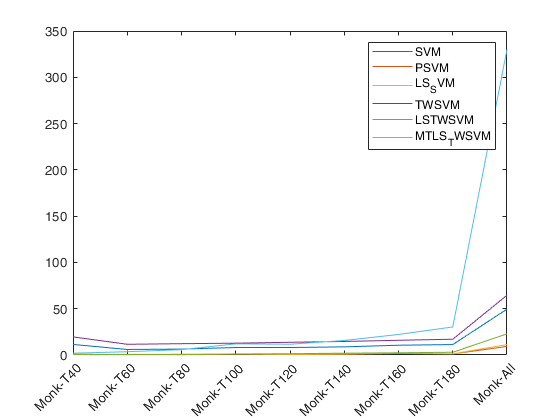

T = Summary.Stats.Time(Monk, STL);
plot(T.Variables);
bar_table(T);

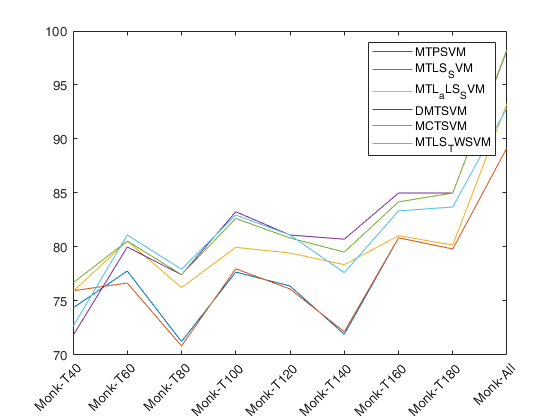

T = Summary.Stats.Accuracy(Monk, MTL);
plot(T.Variables);
bar_table(T);

T = Summary.Stats.Time(Monk, STL);
plot(T.Variables);
bar_table(T);

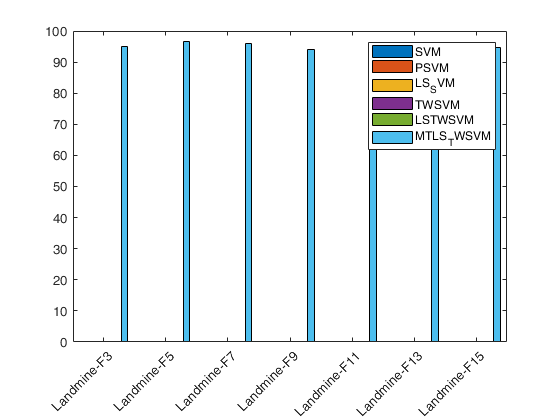

% landmine
Landmine = [40:46];
T = Summary.Stats.Accuracy(Landmine, STL);
bar(T.Variables);
bar_table(T)

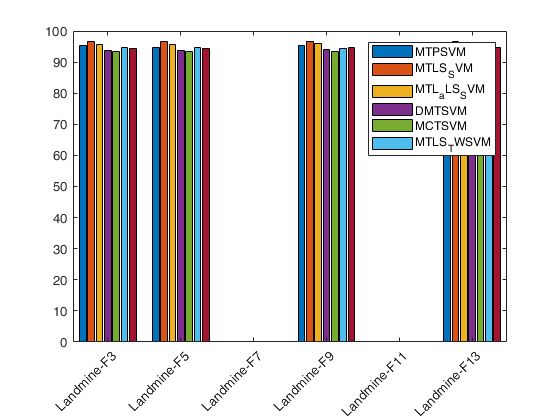

T = Summary.Stats.Accuracy(Landmine, MTL);
bar(T.Variables');
bar_table(T);

function [ ] = bar_table(T)    
    legend(T.Properties.VariableNames);
    xticklabels(T.Row);
    set(gca, 'XTicklabel', T.Row, 'XTickLabelRotation', 45);
end